# Extra 2: Uncertainties Through 2-Parameter Graphical Method

In the tutorial examples, the uncertainties associated with a model's parameters were estimated by using the covariance matrix. Sometimes these matrices aren't easily calculable, or sometimes even singular. An alternative method to uncertainty estimation is based on graphical inspection of the$\chi^2$ function, hence the name "graphical method". This notebook will focus on using the graphical method on a model with a two parameter. In this case, the data is of an exponential distribution. 

First we're going to calculate the uncertainties from the covariance method using the Jocobian. The graphical method does not make use of the Jacobian or curvature matrix. We're just using it as a comparison between the two methods

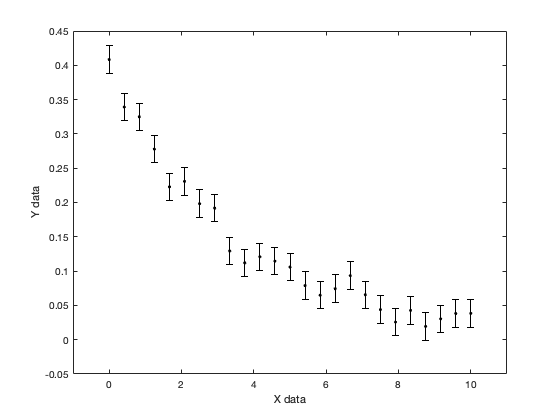

data_path = 'data/';                           
file_name = 'exp_2param.txt';
file_path = strcat(data_path, file_name);
data = dlmread(file_path);    

% split the data into vectors
x_data = data(:, 1);
y_data = data(:, 2);
y_err = data(:, 3);

% plot the data
fig1 = figure;
ax1 = axes(fig1);
errorbar(ax1, x_data, y_data, y_err, 'k.')
ax1.XLim = [-1 11];
xlabel('X data')
ylabel('Y data')

Now we're going to define our 2-parameter function. We'll use the two parameter sto represent both the normalization of the function, as well as it's argument coefficent. 

 
$$f(x| a_{1},a_{2}) = a_{1} \cdot \text{exp}(-a_{2} \cdot x)
$$


Again, we're following the original method of fitting and covriance calculation. Since our model is 2-parameter we expect our matrix to be 2X2 with diagonal entries equal to the variances (i.e. the square of the standard deviations).

% define the fittype for the model function
ft = fittype('b*exp(-c*x)');

% perform the chi-squared minimization
[f, gof, fit_output] = fit(x_data, y_data, ft, 'Weights', y_err.^(-2));


% extract the weighted Jacobian matrix of the model fit
J = fit_output.Jacobian;

% compute the curvature and covariance matrices
curvature_matrix = J' * J;
covariance_matrix = inv(curvature_matrix);

% create vectors for the two parameters around the best fit value
b_vec = linspace(f.b - 0.02, f.b + 0.02, 200);
c_vec = linspace(f.c - 0.02, f.c + 0.02, 200);

% make a meshgrid of the parameter vectors for 3D plotting
[B, C] = meshgrid(b_vec, c_vec);

% instantiate a matrix for chi-squared values and use two loops to compute
% the value for each pairing of parameter values from b_vec and c_vec
chi2 = zeros(size(B));
for i = 1:numel(c_vec)
    for j = 1:numel(b_vec)
        chi2(i, j) = sum( (y_data - b_vec(j)*exp(-c_vec(i)*x_data)).^2 ./ y_err.^2);
    end
end

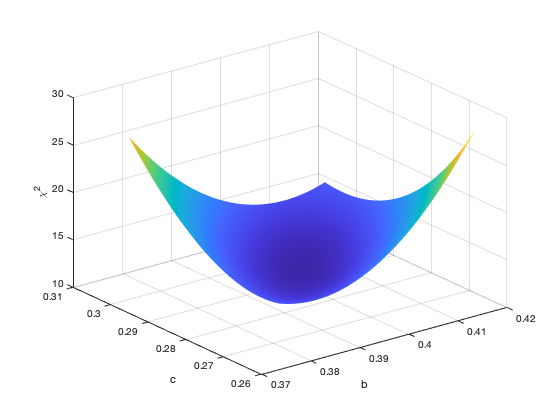

% plot the chi squared surface as a function of the two parameters
fig2 = figure;
ax2 = axes(fig2);
surf(B, C, chi2, 'EdgeColor', 'none')
xlabel(ax2, 'b')
ylabel(ax2, 'c')
zlabel(ax2, '\chi^2')

We will plot the $\chi^2$ function, keeping all of the x, y, and σy data points fixed and varying only the parameter value. Plot the function in the vicinity of the best fit parameter value. The graphical method states that the uncertainty on the best fit parameter is found by looking at the value $\chi^2 =\chi^2_{min} + 1$. The distance from between $a(\chi^2_{min})$ and $a(\chi^2_{min} + 1)$is equal to the error $\sigma_{a}^{graph}$. In the 2-parameter case, we take a slice of the suface plot above at $\chi^2 =\chi^2_{min} + 1$ and the tangent lines for each parameters are used to caculate the $\sigma_{a}^{graph}$.

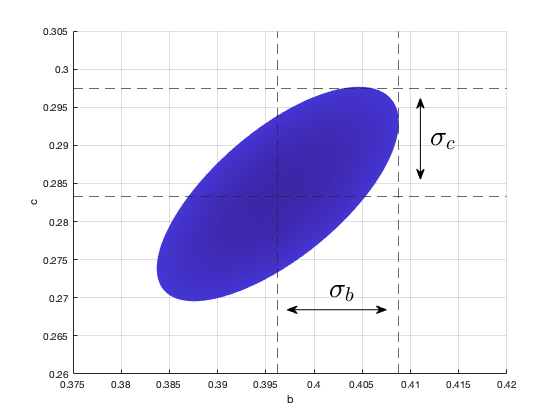

% plot the chi squared surface as a function of the two parameters
fig3 = figure;
ax3 = axes(fig3);
surf(B, C, chi2, 'EdgeColor', 'none')
xlabel(ax3, 'b')
ylabel(ax3, 'c')
zlabel(ax3, '\chi^2')
ax3.ZLim = [gof.sse, gof.sse + 1];
ax3.View = [0, 90];
yline(0.2975,'--','');
yline(0.2833,'--','');
xline(0.4087,'--','');
xline(0.3962,'--','');
annotation('doublearrow',[0.7507 0.7507],[0.7657 0.5734])
annotation('doublearrow',[0.513 0.6898],[0.2625 0.2625])
txtb = text(0.4015, 0.271, ("$\sigma_{b}$"),'Interpreter','latex');
txtb.FontSize = 28;
txtc = text(0.412, 0.291, ("$\sigma_{c}$"),'Interpreter','latex');
txtc.FontSize = 28;